# d11Bsw

## Global Variables

clear
addpath("./../");
addpath("./../Geochemistry_Helpers");

% Default values
pH_Query = 6.5:0.3:11; % X Value at which points are calculated
Fractionation = 27.2; % ‰
pKB = 8.6; % pH Units

% Create Boron Objects
Boron_Objects(numel(pH_Query),1) = Boron_pH();
Boron_Objects.assignToEach("pH",pH_Query);

% Preallocating for later
viable_d11bsw = []; % Empty array, populated when a limit is found
symbol = 0; % Value to track the d11Bsw direction indicator

% Display values
LineWidth = 2; % Controls display
FontSize = 20; % Controls display

colours.boric = [0.8,0.2,0.2];
colours.borate = [0.0,0.6,0.8];
colours.measurement = [0,0,0];
colours.d11B_sw = [0.6,0.2,0.6];


 

## B(OH)3 and B(OH)4- at variable d11Bsw

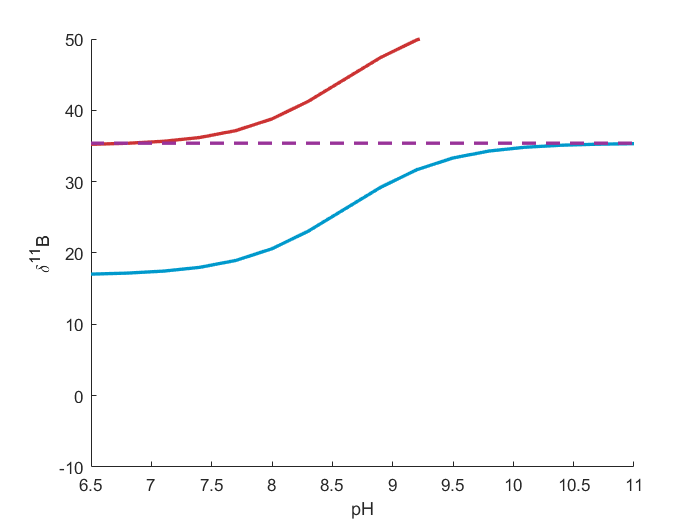

% Assign values to the boron objects
Boron_Objects.assignToAll("d11B_sw",delta("B",35.4));
Boron_Objects.assignToAll("pKb",pX(8.6))
Boron_Objects.assignToAll("epsilon",18.2);
Boron_Objects.assignToAll("d11B_4",delta("B",NaN));
Boron_Objects.calculate();

d11B4 = Boron_Objects.collate("d11B_4").collate("value");
d11B3 = Boron_Objects.collate("d11B_3").collate("value");

%% Plot boric, borate and d11Bsw
clf
hold on
plot(pH_Query,d11B3,'LineWidth',LineWidth,'Color',colours.boric);
plot(pH_Query,d11B4,'LineWidth',LineWidth,'Color',colours.borate);
plot([min(pH_Query),max(pH_Query)],[Boron_Objects(1).d11B_sw.value,Boron_Objects(1).d11B_sw.value],'--','LineWidth',LineWidth,'Color',colours.d11B_sw)

xlim([min(pH_Query),max(pH_Query)])
ylim([-10,50])

xlabel("pH")
ylabel("\delta^{11}B")

**Key Points:**

- Constant $\delta^{11} B$ offset between ${B\left(\textrm{OH}\right)}_3$ and ${B\left(\textrm{OH}\right)}_4^-$

- $\delta^{11} {\mathrm{B}}_{\textrm{sw}} =\delta^{11} {B\left(\textrm{OH}\right)}_3$ at low pH

- $\delta^{11} {\mathrm{B}}_{\textrm{sw}} =\delta^{11} {B\left(\textrm{OH}\right)}_4^-$ at high pH

- Changing $\delta^{11} B_{\textrm{sw}}$ shifts the curves up and down

## Single borate measurement

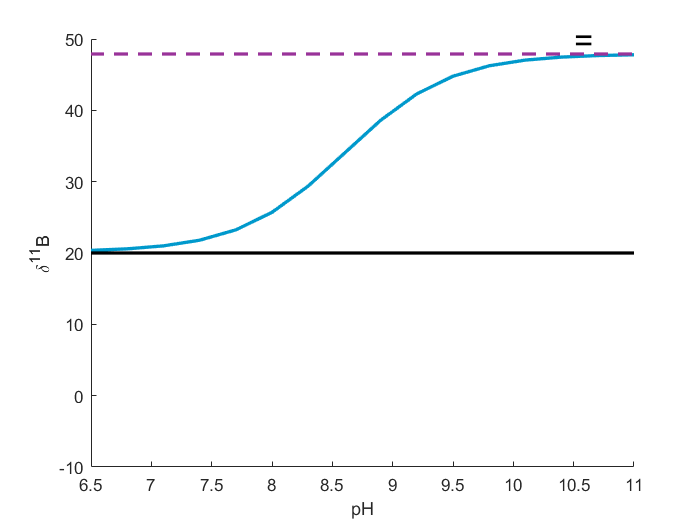

% Imagine one borate measurement (can be any value)
measurements = Boron_pH();
measurements.d11B_4 = delta("B",20);

measurements.d11B_sw = delta("B",47.3);
measurements.pKb = pX(8.6);
measurements.epsilon = 27.2;

% Do d11B4->pH
measurements.calculate();

% Assign values to the boron objects
Boron_Objects.assignToAll("d11B_sw",measurements.d11B_sw);
Boron_Objects.assignToAll("pKb",measurements.pKb);
Boron_Objects.assignToAll("epsilon",measurements.epsilon);
Boron_Objects.assignToAll("d11B_4",delta("B",NaN));
Boron_Objects.calculate();

% Simulate boric and borate curves at specified d11Bsw
d11B4 = Boron_Objects.collate("d11B_4").collate("value");
d11B3 = Boron_Objects.collate("d11B_3").collate("value");


% Add annotation
if measurements.d11B_4.value <=max(d11B4) && measurements.d11B_4.value>=min(d11B4)
    text(10.5,50,"=",'FontSize',FontSize)
elseif measurements.d11B_4.value<=max(d11B4)
    text(10.5,50,"\downarrow",'FontSize',FontSize)
elseif measurements.d11B_4.value>=min(d11B4)
    text(10.5,50,"\uparrow",'FontSize',FontSize)
end

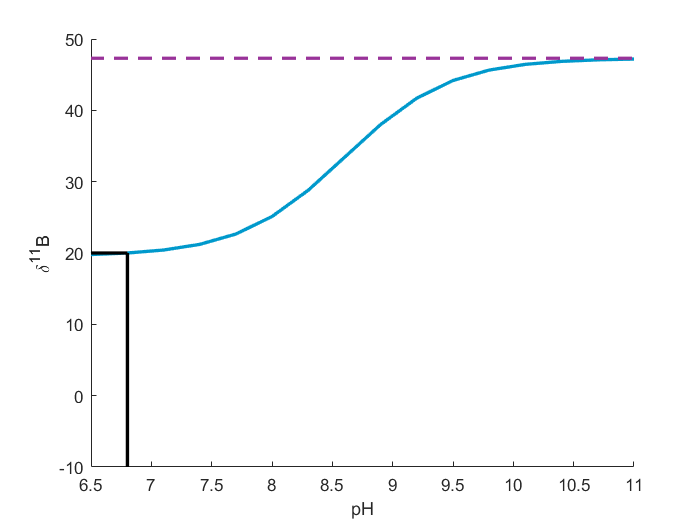


% Plot the measurement, borate curve and d11Bsw
clf
hold on
plot(pH_Query,d11B4,'LineWidth',LineWidth,'Color',colours.borate);
plot([min(pH_Query),max(pH_Query)],[measurements.d11B_sw.value,measurements.d11B_sw.value],'--','LineWidth',LineWidth,'Color',colours.d11B_sw)

% Plot the dual pH lines
if ~isreal(measurements.pH.pValue)
    plot([min(pH_Query),max(pH_Query)],[measurements.d11B_4.value,measurements.d11B_4.value],'LineWidth',LineWidth,'Color',colours.measurement);
else
    plot([pH_Query(1),measurements.pH.pValue],[measurements.d11B_4.value,measurements.d11B_4.value],'LineWidth',LineWidth,'Color',colours.measurement);
    plot([measurements.pH.pValue,measurements.pH.pValue],[-10,measurements.d11B_4.value],'LineWidth',LineWidth,'Color',colours.measurement);
end

% Configure axes
xlim([min(pH_Query),max(pH_Query)])
ylim([-10,50])

xlabel("pH")
ylabel("\delta^{11}B")

**Key Points:**

- The shape of the curve means even a single $\delta^{11} {B\left(\textrm{OH}\right)}_4^-$ measurement gives some constraint on $\delta^{11} B_{\textrm{sw}}$

## Dual borate measurement globals

viable_d11bsw = []; % Empty array, populated when a limit is found
symbol = 0; % Value to track the d11Bsw direction indicator
 

## Dual borate measurement

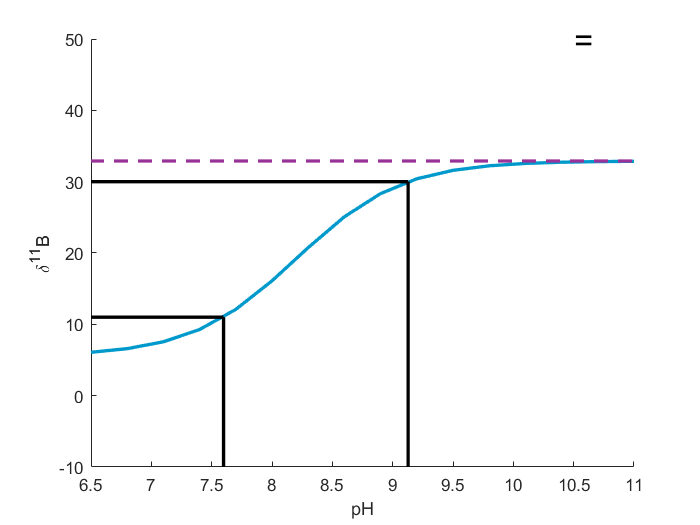

% Do the d11B4->pH
measurements = [Boron_pH(),Boron_pH()];
measurements(1).d11B_4 = delta("B",11); % Imagine two measurements, can be any values
measurements(2).d11B_4 = delta("B",30);
measurements.assignToAll("d11B_sw",delta("B",32.9));
measurements.assignToAll("pKb",pX(8.2));

measurements.calculate();


% Simulate the borate d11B-pH curve
Boron_Objects.assignToAll("d11B_sw",measurements(1).d11B_sw);
Boron_Objects.assignToAll("pKb",measurements(1).pKb);
Boron_Objects.assignToAll("epsilon",measurements(1).epsilon);
Boron_Objects.assignToAll("d11B_4",delta("B",NaN));
Boron_Objects.calculate();

% Simulate boric and borate curves at specified d11Bsw
d11B4 = Boron_Objects.collate("d11B_4").collate("value");


% Plot borate curve, d11Bsw, and both measurements
clf
hold on
plot(pH_Query,d11B4,'LineWidth',LineWidth,'Color',colours.borate);
plot([min(pH_Query),max(pH_Query)],[measurements(1).d11B_sw.value,measurements(1).d11B_sw.value],'--','LineWidth',LineWidth,'Color',colours.d11B_sw)

% Plot the dual pH lines
for measurement_index = 1:numel(measurements)
    if ~isreal(measurements(measurement_index).pH.pValue)
        plot([min(pH_Query),max(pH_Query)],[measurements(measurement_index).d11B_4.value,measurements(measurement_index).d11B_4.value],'LineWidth',LineWidth,'Color',colours.measurement);
    else
        plot([pH_Query(1),measurements(measurement_index).pH.pValue],[measurements(measurement_index).d11B_4.value,measurements(measurement_index).d11B_4.value],'LineWidth',LineWidth,'Color',colours.measurement);
        plot([measurements(measurement_index).pH.pValue,measurements(measurement_index).pH.pValue],[-10,measurements(measurement_index).d11B_4.value],'LineWidth',LineWidth,'Color',colours.measurement);
    end
end

% Add symbol to upper right
if all(measurements.collate("d11B_4").collate("value")<=max(d11B4)) && all(measurements.collate("d11B_4").collate("value")>=min(d11B4))
    old_symbol = symbol;
    symbol = 0;
    text(10.5,50,"=",'FontSize',FontSize)
elseif any(measurements.collate("d11B_4").collate("value")<min(d11B4))
    old_symbol = symbol;
    symbol = -1;
    text(10.5,50,"\downarrow",'FontSize',FontSize)
elseif any(measurements.collate("d11B_4").collate("value")>max(d11B4))
    old_symbol = symbol;
    symbol = 1;
    text(10.5,50,"\uparrow",'FontSize',FontSize)
end

symbol_change = abs(symbol-old_symbol);

if symbol_change>0
    if any(abs(measurements(1).d11B_sw.value-viable_d11bsw)>5) || isempty(viable_d11bsw)
        viable_d11bsw = [viable_d11bsw,measurements(1).d11B_sw.value];
    end
end

% Plot any found limits
for index=1:numel(viable_d11bsw)
    plot([min(pH_Query),max(pH_Query)],[viable_d11bsw(index),viable_d11bsw(index)],'LineWidth',LineWidth,'Color',colours.d11B_sw)
end

% Configure axes
xlim([min(pH_Query),max(pH_Query)])
ylim([-10,50])

xlabel("pH")
ylabel("\delta^{11}B")

**Key Points:**

- Two different $\delta^{11} {B\left(\textrm{OH}\right)}_4^-$ measurements give greater constraint

- If separated by the fractionation factor (27.2‰), the curve is completed constrained

- Looking simultaneously in low and high pH environments could constrain $\delta^{11} B_{\textrm{sw}}$

## Delta pH Globals

viable_d11bsw = [];
 

## Delta pH

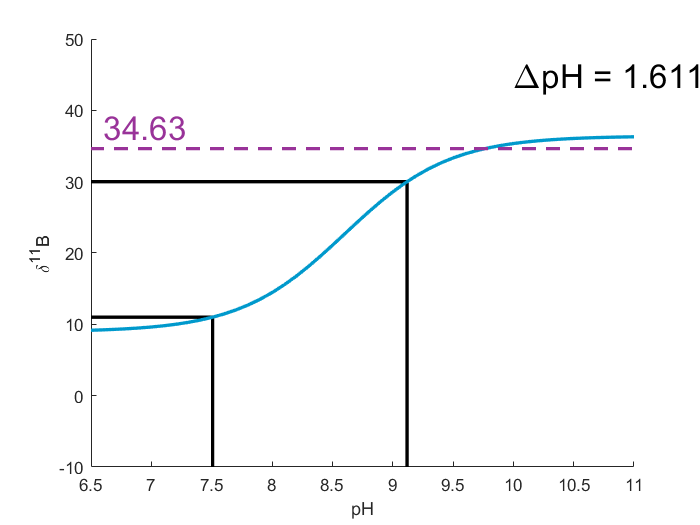

pH_Query = 6.5:0.1:11;

% New pH_Query so remake the Boron Objects
Boron_Objects = Boron_pH.empty();
Boron_Objects(numel(pH_Query),1) = Boron_pH();
Boron_Objects.assignToEach("pH",pH_Query);

% Then assign other parameters
Boron_Objects.assignToAll("epsilon",Fractionation);
Boron_Objects.assignToAll("pKb",pX(8.6));

measurements = [Boron_pH(),Boron_pH()];
measurements(1).d11B_4 = delta("B",11); % Imagine two measurements, can be any values
measurements(2).d11B_4 = delta("B",30);
measurements.assignToAll("d11B_sw",delta("B",36.4));
measurements.assignToAll("pKb",pX(8.6));

measurements.calculate();


delta_pH = 1;

% Simulate the borate d11B-pH curve
Boron_Objects.assignToAll("d11B_sw",measurements(1).d11B_sw);
Boron_Objects.assignToAll("d11B_4",delta("B",NaN));
Boron_Objects.calculate();

d11B4 = Boron_Objects.collate("d11B_4").collate("value");

clf
hold on
% Plot the dual pH lines
for measurement_index = 1:numel(measurements)
    if ~isreal(measurements(measurement_index).pH.pValue)
        plot([min(pH_Query),max(pH_Query)],[measurements(measurement_index).d11B_4.value,measurements(measurement_index).d11B_4.value],'LineWidth',LineWidth,'Color',colours.measurement);
    else
        plot([pH_Query(1),measurements(measurement_index).pH.pValue],[measurements(measurement_index).d11B_4.value,measurements(measurement_index).d11B_4.value],'LineWidth',LineWidth,'Color',colours.measurement);
        plot([measurements(measurement_index).pH.pValue,measurements(measurement_index).pH.pValue],[-10,measurements(measurement_index).d11B_4.value],'LineWidth',LineWidth,'Color',colours.measurement);
    end
end
if all(isreal([measurements(1).pH.pValue,measurements(2).pH.pValue]))
    delta_pH_measured = abs(measurements(2).pH.pValue-measurements(1).pH.pValue);
else
    delta_pH_measured = NaN;
end

text(10,45,"\DeltapH = "+num2str(delta_pH_measured),'FontSize',FontSize);
text(6.6,d11B_sw+3,num2str(d11B_sw),'Color',colours.d11B_sw,'FontSize',FontSize)

plot(pH_Query,d11B4,'Color',colours.borate,'LineWidth',LineWidth);
plot([min(pH_Query),max(pH_Query)],[d11B_sw,d11B_sw],'--','LineWidth',LineWidth,'Color',colours.d11B_sw)

if (delta_pH_measured>delta_pH-0.05)&&(delta_pH_measured<delta_pH+0.05)
    viable_d11bsw = [viable_d11bsw,d11B_sw];
end

for index = 1:numel(viable_d11bsw)
    plot([min(pH_Query),max(pH_Query)],[viable_d11bsw(index),viable_d11bsw(index)],'LineWidth',LineWidth,'Color',colours.d11B_sw)
end

xlim([min(pH_Query),max(pH_Query)])
ylim([-10,50])

xlabel("pH")
ylabel("\delta^{11}B")

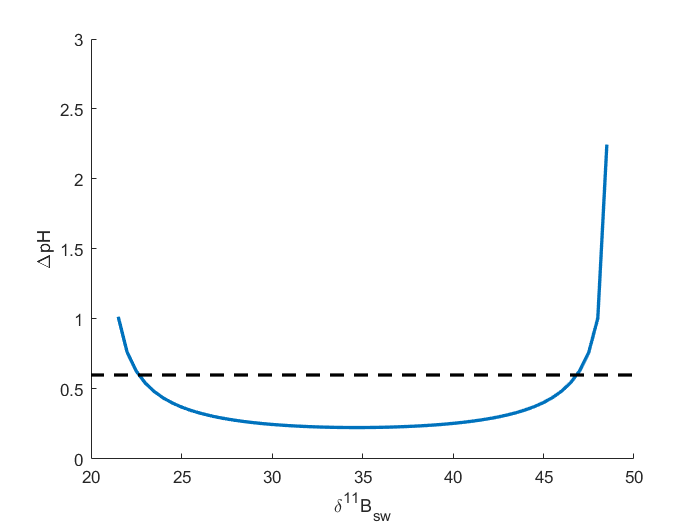

d11B_sw = 20:0.5:50;
Boron_Objects_1 = [];
Boron_Objects_2 = [];
current = 1;
for dbsw = d11B_sw
    Boron_Objects_1 = [Boron_Objects_1,Boron_pH()];
    Boron_Objects_1(current).d11B_sw = delta("B",dbsw);
    
    Boron_Objects_2 = [Boron_Objects_2,Boron_pH()];
    Boron_Objects_2(current).d11B_sw = delta("B",dbsw);
    
    current = current + 1;
end
pKb = 8.6;
Fractionation = 31;

Boron_Objects_1.assignToAll("epsilon",Fractionation);
Boron_Objects_1.assignToAll("pKb",pX(pKb));

Boron_Objects_2.assignToAll("epsilon",Fractionation);
Boron_Objects_2.assignToAll("pKb",pX(pKB));

measured_d11B = [17,21];
delta_pH = 0.6;

Boron_Objects_1.assignToAll("d11B_4",delta("B",measured_d11B(1)));
Boron_Objects_2.assignToAll("d11B_4",delta("B",measured_d11B(2)));

Boron_Objects_1.calculate();
Boron_Objects_2.calculate();

delta_pH_measured = nan(1,numel(d11B_sw));

for d11B_index = 1:numel(Boron_Objects_1)
    if isreal(Boron_Objects_1(d11B_index).pH.pValue) && isreal(Boron_Objects_2(d11B_index).pH.pValue)
        delta_pH_measured(d11B_index) = abs(Boron_Objects_1(d11B_index).pH.pValue-Boron_Objects_2(d11B_index).pH.pValue);
    else
    end
end

clf
hold on
plot(d11B_sw,delta_pH_measured,'LineWidth',LineWidth)
plot([min(d11B_sw),max(d11B_sw)],[delta_pH,delta_pH],'--','Color','k','LineWidth',LineWidth)

xlim([min(d11B_sw),max(d11B_sw)]);
ylim([0,3]);

xlabel("\delta^{11}B_{sw}")
ylabel("\DeltapH")

**Key Points:**

- For the same $\Delta \delta^{11} {B\left(\textrm{OH}\right)}_4^-$, changing $\delta^{11} B_{\textrm{sw}}$ changes the calculated $\Delta \textrm{pH}$

- If $\Delta \textrm{pH}$ is known (or assumed) independently, $\delta^{11} B_{\textrm{sw}}$ can be tuned to give the correct $\Delta \textrm{pH}$

- Because the $\delta^{11} {B\left(\textrm{OH}\right)}_4^-$ curve is symmetrical, there will sometimes be two solutions, which are equally spaced either side of pKb.

## **pH Does Not Exist In Isolation**

$\textrm{pH}\to \Omega_{\textrm{cal}}$ (assuming second carbonate system parameter)

If $\Omega <1$ the foram would have dissolved

If $\Omega >1$ there would be abiotic carbonate alongside the foram

Some studies have assumed $5\le \Omega \le 7\ldotp 5$ for the surface ocean

    Perhaps reasonable because $\textrm{CCD}>\textrm{deepest}\;\textrm{sample}$

    Could do with a more quantitative basis

$\Delta \textrm{pH}\to \Delta \textrm{DIC}$ (assuming second carbonate system parameter)

$\Delta \textrm{DIC}\to \Delta O_2$ (using a Redfield ratio)

Assuming C:O of **106:138**


$$\Delta O_2 \approx 1\ldotp 3\Delta \textrm{DIC}$$


Surface $O_2$ can be calculated from Henry's law (given Temperature/Salinity/Pressure)

If deep $O_2$ is too anoxic for forams, it's potentially implausible and the second carbonate system parameter or $\delta^{11} B_{\textrm{sw}}$ needs to be adjusted

Need to be careful not to introduce circular logic

## Results So Far...

53.2-40.3Ma: 38.2 - 38.9‰ Anagnostou *et al.*, 2016

23-12Ma: ~37.5 Greenop *et al.*, 2017

66.82-65.61Ma: 39.05-39.85‰ Henehan *et al.,* 2019

40.5-40.1Ma: 38.5-38.9‰ Henehan* et al.*, 2020

0Ma: 39.61 Foster *et al.* 2010

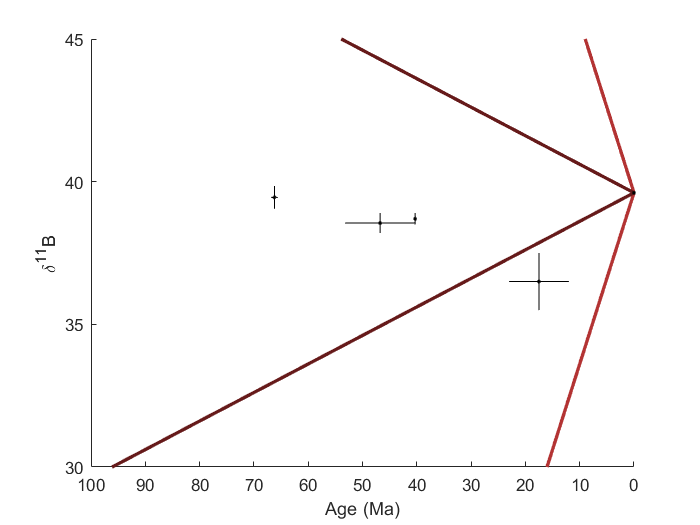

Ages = [53.2,40.3;23,12;66.82,65.61;40.5,40.1;0,0];
d11B_sws = [38.2,38.9;35.5,37.5;39.05,39.85;38.5,38.9;39.61,39.61];

d11B_modern = 39.61;
rate_of_change = 0.6; % ‰/Myr Lemarchand 2000/2002

time_range = 0:100;
d11B_potential = NaN(numel(time_range),2);
d11B_potential(1,1) = d11B_modern;
d11B_potential(1,2) = d11B_modern;

clf
hold on
for time=2:time_range(end);
    d11B_potential(time,1) = d11B_potential(time-1,1)+rate_of_change;
    d11B_potential(time,2) = d11B_potential(time-1,2)-rate_of_change;
end
plot(time_range,d11B_potential(:,1),'Color',[0.7,0.2,0.2],'LineWidth',LineWidth)
plot(time_range,d11B_potential(:,2),'Color',[0.7,0.2,0.2],'LineWidth',LineWidth)

rate_of_change = 0.1; % ‰/Myr Lemarchand 2000/2002
for time=2:time_range(end);
    d11B_potential(time,1) = d11B_potential(time-1,1)+rate_of_change;
    d11B_potential(time,2) = d11B_potential(time-1,2)-rate_of_change;
end
plot(time_range,d11B_potential(:,1),'Color',[0.4,0.1,0.1],'LineWidth',LineWidth)
plot(time_range,d11B_potential(:,2),'Color',[0.4,0.1,0.1],'LineWidth',LineWidth)

for index=1:size(Ages,1)
    plot(Ages(index,:),[sum(d11B_sws(index,:))/2,sum(d11B_sws(index,:))/2],'k');
    plot([sum(Ages(index,:))/2,sum(Ages(index,:))/2],d11B_sws(index,:),'k');
    plot(sum(Ages(index,:))/2,sum(d11B_sws(index,:))/2,'k.')
end
xlim([0,time_range(end)]);
ylim([30,45]);

xlabel("Age (Ma)")
ylabel("\delta^{11}B")

set(gca,'XDir','Reverse');

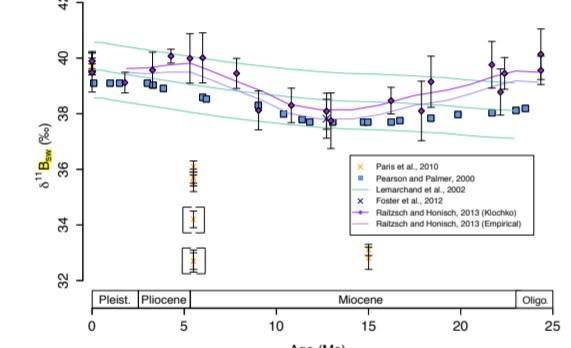

## Simple vs Complex

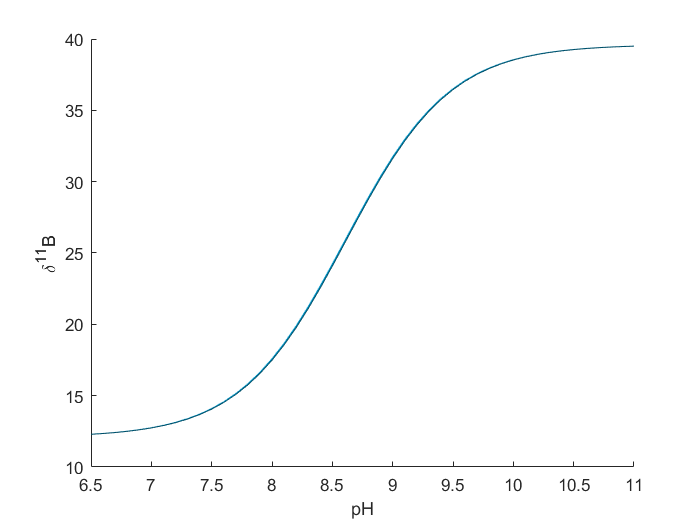

Boron_Objects = Boron_pH.empty();
Boron_Objects(numel(pH_Query),1) = Boron_pH();
Boron_Objects.assignToEach("pH",pH_Query);

Boron_Objects.assignToAll("epsilon",Fractionation);
Boron_Objects.assignToAll("pKb",pX(pKB));

Boron_Objects.assignToAll("d11B_4",delta("B",NaN));
Boron_Objects.calculate();
complex_d11B_4 = Boron_Objects.collate("d11B_4").collate("value");

Boron_Objects.assignToAll("d11B_4",delta("B",NaN));
Boron_Objects.calculate(1);
simple_d11B_4 = Boron_Objects.collate("d11B_4").collate("value");

clf
hold on
plot(pH_Query,complex_d11B_4,'LineWidth',0.5,'Color',colours.borate);
plot(pH_Query,simple_d11B_4,'LineWidth',0.5,'Color',colours.borate./2);

xlabel("pH");
ylabel("\delta^{11}B");

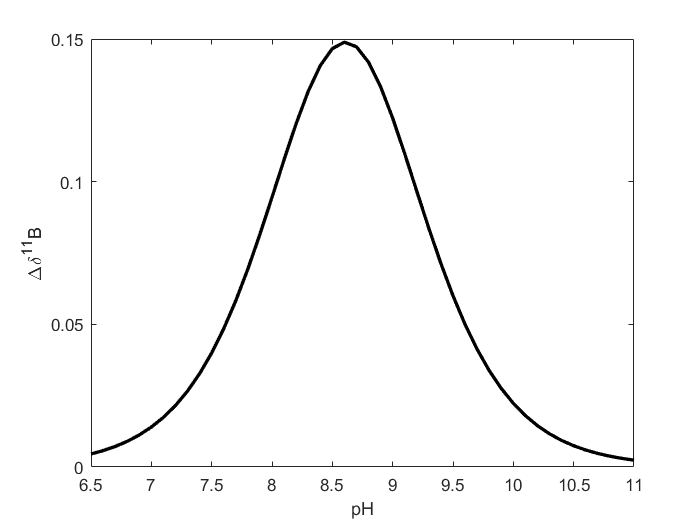


figure()
clf
plot(pH_Query,abs(complex_d11B_4-simple_d11B_4),'Color','k','LineWidth',LineWidth);

xlabel("pH");
ylabel("\Delta\delta^{11}B");

**Key Points:**

- There are two ways of performing the mass balance for isotopes (a '*true*' way and an approximation).

- The difference between the two methods is shown, and reaches a maximum of ~0.15‰ in the region of pKb.

## d11B Curve Emulator

function d11B = Maked11BCurve(pH_i,d11B_sw,Offset,pKb,Width)
    Maximum = d11B_sw;
    Minimum = d11B_sw-Offset;
    Centre = pKb;
    
    d11B = Minimum+(0.5*(erf((pH_i-Centre)/Width) +1)*Offset);
end